clc;
clear;

% User's existing code
syms s1_x s1_y s1_z s2_x s2_y s2_z s3_x s3_y s3_z real % center of servo rotation
syms q1_x q1_y q1_z q2_x q2_y q2_z q3_x q3_y q3_z real % end of servo horn
syms p1_x p1_y p1_z p2_x p2_y p2_z p3_x p3_y p3_z real % connection of pitch link to swash plate
syms theta_1 theta_2 theta_3 real

% Define symbolic constants for radii and z_c
syms r r_s real % r: servo placement radius, r_s: servo horn length
syms r_p real % r_p: length of the pitch link (distance |p_i - q_i|)
syms r_w real % r_w: radius of the swashplate circle (circle of points p)
syms z_c real % z_c: z-coordinate of the swashplate circle center

% Assume radii are positive for simplifications like sqrt(r^2)=r
assume(r > 0);
assume(r_s > 0);
assume(r_p > 0);
assume(r_w > 0);

% Placeholder matrices (will be overwritten or used for storing final p values)
p_symbolic_vars = [
    p1_x , p2_x, p3_x ;
    p1_y , p2_y, p3_y ;
    p1_z , p2_z, p3_z ;
    ];
% q_symbolic_vars = [ % This q is a placeholder for symbolic names
%     q1_x , q2_x, q3_x ;
%     q1_y , q2_y, q3_y ;
%     q1_z , q2_z, q3_z ;
%     ];
s = [
    s1_x , s2_x, s3_x ;
    s1_y , s2_y, s3_y ;
    s1_z , s2_z, s3_z ;
    ];

theta_vec = [theta_1, theta_2, theta_3]; % Vector of theta angles

% The spacing of servos around the unit circle
gamma = 2*pi/3;
angles = [0, gamma, 2*gamma]; % Servo mounting angles

% Assign values of s (servo base positions)
fprintf('Calculating servo base positions (s_i)...\n');

Calculating servo base positions (s_i)...


for i = 1:3
    servo_angle = angles(i);
    s(:,i) = [r*cos(servo_angle); r*sin(servo_angle); 0];  % point on circle in xy-plane at z=0
end
disp('Calculated s matrix:');

Calculated s matrix:


disp(s);

$$\left(\begin{array}{ccc} r & -\frac{r}{2} & -\frac{r}{2}\\ 0 & \frac{\sqrt{3}\,r}{2} & -\frac{\sqrt{3}\,r}{2}\\ 0 & 0 & 0 \end{array}\right)$$


% NORMAL VECTORS TO S (These are unit vectors in direction of s_i in xy-plane)
fprintf('\nCalculating unit vectors n_i (in direction of s_i)...\n');


Calculating unit vectors n_i (in direction of s_i)...


norms_s = simplify(sqrt(sum(s.^2, 1))); % Should be 'r' for each column
n = simplify(s ./ norms_s);
disp('Calculated n matrix (unit vectors for s_i):');

Calculated n matrix (unit vectors for s_i):


disp(n);

$$\left(\begin{array}{ccc} 1 & -\frac{1}{2} & -\frac{1}{2}\\ 0 & \frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{2}\\ 0 & 0 & 0 \end{array}\right)$$


% First multiply (Dot product check, should be 'r' for each column)
% d = simplify(sum(n .* s, 1)); 
% disp('Dot product n_i . s_i (should be r):');
% disp(d);

% Servo horn tip displacements in their local 2D planes
% servo_tips_local_u will be r_s * cos(theta_i)
% servo_tips_local_v will be r_s * sin(theta_i)
servo_tips_local_u = r_s .* cos(theta_vec); % Displacement along u-axis for each servo
servo_tips_local_v = r_s .* sin(theta_vec); % Displacement along v-axis for each servo

% 1) build two in-plane basis vectors (u tangent to the circle, v = n x u)
fprintf('\nCalculating basis vectors u_i (tangential) and v_i (axial)...\n');


Calculating basis vectors u_i (tangential) and v_i (axial)...


u = [-s(2,:);  % More robust: u = [-n(2,:); n(1,:); zeros(1,3)];
      s(1,:); 
      zeros(1,3)];         
u = u ./ sqrt(sum(u.^2,1)); % Normalize each column; should simplify to use n
% Simplified u using n:
u = [-n(2,:);
      n(1,:);
      zeros(1,3)];
disp('Calculated u matrix (tangential vectors):');

Calculated u matrix (tangential vectors):


disp(simplify(u));

$$\left(\begin{array}{ccc} 0 & -\frac{\sqrt{3}}{2} & \frac{\sqrt{3}}{2}\\ 1 & -\frac{1}{2} & -\frac{1}{2}\\ 0 & 0 & 0 \end{array}\right)$$


v = cross(n, u, 1); % Second in-plane axis, v_i should be [0;0;1]
disp('Calculated v matrix (axial vectors, should be [0;0;1] for each column):');

Calculated v matrix (axial vectors, should be [0;0;1] for each column):


disp(simplify(v)); % Should be [0;0;1] for each column

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$


% 2) map your 2D servo_tips into a 3D delta vector for each servo horn
fprintf('\nCalculating delta_i vectors (displacement from s_i to q_i)...\n');


Calculating delta_i vectors (displacement from s_i to q_i)...


delta = u .* servo_tips_local_u + v .* servo_tips_local_v;
disp('Calculated delta matrix:');

Calculated delta matrix:


disp(simplify(delta));

$$\left(\begin{array}{ccc} 0 & -\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2} & \frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ r_{s}\,\cos\left(\theta_{1}\right) & -\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2} & -\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)$$


% 3) the 3D endpoints of the servo-horns (q_i)
fprintf('\nCalculating servo horn tip positions q_i = s_i + delta_i...\n');


Calculating servo horn tip positions q_i = s_i + delta_i...


q_calculated = s + delta;
q_calculated = simplify(q_calculated);
disp('Calculated q matrix (q_i coordinates):');

Calculated q matrix (q_i coordinates):


disp(q_calculated);

$$\begin{array}{l} \left(\begin{array}{ccc} r & -\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2} & \frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}-\frac{r}{2}\\ r_{s}\,\cos\left(\theta_{1}\right) & \sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2} & -\sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,r}{2} \end{array}$$


% Now, derive p_i from q_i using the established formulas

% Initialize cell arrays to store the two solutions for each p_i
% Each element p_solutions{i,j} will be a 3x1 symbolic vector [x; y; z]
p_solutions_set1 = sym(zeros(3,3)); % For the +sqrt(D_sq) solution for x, -sqrt(D_sq) for y
p_solutions_set2 = sym(zeros(3,3)); % For the -sqrt(D_sq) solution for x, +sqrt(D_sq) for y

fprintf('\n---------------------------------------------------------------------\n');


---------------------------------------------------------------------


fprintf('--- Deriving expressions for p_i based on q_i, r_w, r_p, z_c ---\n');

--- Deriving expressions for p_i based on q_i, r_w, r_p, z_c ---


fprintf('---------------------------------------------------------------------\n');

---------------------------------------------------------------------



for i = 1:3
    fprintf('For point p_%d (derived from q_%d which depends on theta_%d):\n', i, i, i);
    
    current_theta = theta_vec(i); % theta_1, theta_2, or theta_3
    
    % Extract coordinates of q_i
    x_qi = q_calculated(1,i);
    y_qi = q_calculated(2,i);
    z_qi = q_calculated(3,i); % This simplifies to r_s * sin(current_theta)
    
    fprintf('  q_%d_x = %s\n', i, char(x_qi));
    fprintf('  q_%d_y = %s\n', i, char(y_qi));
    fprintf('  q_%d_z = %s\n', i, char(z_qi));
    
    % Calculate rho_i_sq = x_qi^2 + y_qi^2
    % As derived in thought process: rho_i_sq = r^2 + r_s^2*cos(current_theta)^2
    % Let's verify this with the symbolic engine for robustness
    rho_sq_i_calc = simplify(x_qi^2 + y_qi^2);
    rho_sq_i_expected = r^2 + r_s^2*cos(current_theta)^2;
    
    % Check if the simplification matches
    if isequal(simplify(rho_sq_i_calc - rho_sq_i_expected), sym(0))
        rho_sq_i = rho_sq_i_expected;
        fprintf('  rho_%d_sq (x_qi^2+y_qi^2) simplifies to: %s\n', i, char(rho_sq_i));
    else
        rho_sq_i = rho_sq_i_calc;
        fprintf('  rho_%d_sq (x_qi^2+y_qi^2) = %s\n', i, char(rho_sq_i));
        fprintf('  Warning: Expected simplification rho_sq_i = r^2 + r_s^2*cos(theta_%d)^2 did not match symbolic result.\n',i);
    end
    
    % Assuming r > 0, rho_sq_i will not be zero unless r=0 and r_s*cos(theta)=0.
    % If r=0, then s_i are all at origin. q_i depends only on delta.
    % If r is strictly positive, rho_sq_i > 0.
    
    % Calculate K_i = r_w^2 + rho_i_sq + (z_c - z_qi)^2 - r_p^2
    K_i = r_w^2 + rho_sq_i + (z_c - z_qi)^2 - r_p^2;
    K_i = simplify(K_i);
    fprintf('  K_%d = %s\n', i, char(K_i));
    
    % Calculate D_sq_i (discriminant term under the square root)
    % D_sq_i = 4*r_w^2*rho_sq_i - K_i^2
    D_sq_i = 4*r_w^2*rho_sq_i - K_i^2;
    D_sq_i = simplify(D_sq_i);
    fprintf('  D_sq_%d (discriminant term) = %s\n', i, char(D_sq_i));
    fprintf('  For real solutions for (p_x, p_y), D_sq_%d must be >= 0.\n', i);
    
    % Calculate the two solutions for (p_xi, p_yi)
    % Solution 1:
    %   p_xi_sol1 = (x_qi * K_i + y_qi * sqrt(D_sq_i)) / (2*rho_sq_i)
    %   p_yi_sol1 = (y_qi * K_i - x_qi * sqrt(D_sq_i)) / (2*rho_sq_i)
    % Solution 2:
    %   p_xi_sol2 = (x_qi * K_i - y_qi * sqrt(D_sq_i)) / (2*rho_sq_i)
    %   p_yi_sol2 = (y_qi * K_i + x_qi * sqrt(D_sq_i)) / (2*rho_sq_i)
    
    % Denominator (2*rho_sq_i)
    den_i = 2*rho_sq_i;
    
    sqrt_D_sq_i = sqrt(D_sq_i); % Symbolic square root
    
    p_xi_sol1 = simplify((x_qi * K_i + y_qi * sqrt_D_sq_i) / den_i);
    p_yi_sol1 = simplify((y_qi * K_i - x_qi * sqrt_D_sq_i) / den_i);
    p_zi_sol = z_c; % z-coordinate is z_c for all p points
    
    p_solutions_set1(:,i) = [p_xi_sol1; p_yi_sol1; p_zi_sol];
    
    p_xi_sol2 = simplify((x_qi * K_i - y_qi * sqrt_D_sq_i) / den_i);
    p_yi_sol2 = simplify((y_qi * K_i + x_qi * sqrt_D_sq_i) / den_i);
    
    p_solutions_set2(:,i) = [p_xi_sol2; p_yi_sol2; p_zi_sol];
    
    fprintf('  Solution 1 for p_%d (using +y_qi*sqrt(D_sq), -x_qi*sqrt(D_sq)):\n', i);
    fprintf('    p_%d_x1 = %s\n', i, char(p_xi_sol1));
    fprintf('    p_%d_y1 = %s\n', i, char(p_yi_sol1));
    fprintf('    p_%d_z1 = %s\n', i, char(p_zi_sol));
    
    fprintf('  Solution 2 for p_%d (using -y_qi*sqrt(D_sq), +x_qi*sqrt(D_sq)):\n', i);
    fprintf('    p_%d_x2 = %s\n', i, char(p_xi_sol2));
    fprintf('    p_%d_y2 = %s\n', i, char(p_yi_sol2));
    fprintf('    p_%d_z2 = %s\n', i, char(p_zi_sol));
    fprintf('-------------------------------------\n');
end

For point p_1 (derived from q_1 which depends on theta_1):


  q_1_x = r


  q_1_y = r_s*cos(theta_1)


  q_1_z = r_s*sin(theta_1)


  rho_1_sq (x_qi^2+y_qi^2) simplifies to: r_s^2*cos(theta_1)^2 + r^2


  K_1 = r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1)


  D_sq_1 (discriminant term) = 4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2


  For real solutions for (p_x, p_y), D_sq_1 must be >= 0.


  Solution 1 for p_1 (using +y_qi*sqrt(D_sq), -x_qi*sqrt(D_sq)):


    p_1_x1 = (r*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1)) + r_s*cos(theta_1)*(4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2)^(1/2))/(2*r_s^2*cos(theta_1)^2 + 2*r^2)


    p_1_y1 = -(r*(4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2)^(1/2) - r_s*cos(theta_1)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1)))/(2*r_s^2*cos(theta_1)^2 + 2*r^2)


    p_1_z1 = z_c


  Solution 2 for p_1 (using -y_qi*sqrt(D_sq), +x_qi*sqrt(D_sq)):


    p_1_x2 = (r*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1)) - r_s*cos(theta_1)*(4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2)^(1/2))/(2*r_s^2*cos(theta_1)^2 + 2*r^2)


    p_1_y2 = (r*(4*r_w^2*(r_s^2*cos(theta_1)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1))^2)^(1/2) + r_s*cos(theta_1)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_1)))/(2*r_s^2*cos(theta_1)^2 + 2*r^2)


    p_1_z2 = z_c


-------------------------------------


For point p_2 (derived from q_2 which depends on theta_2):


  q_2_x = - r/2 - (3^(1/2)*r_s*cos(theta_2))/2


  q_2_y = (3^(1/2)*r)/2 - (r_s*cos(theta_2))/2


  q_2_z = r_s*sin(theta_2)


  rho_2_sq (x_qi^2+y_qi^2) simplifies to: r_s^2*cos(theta_2)^2 + r^2


  K_2 = r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2)


  D_sq_2 (discriminant term) = 4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2


  For real solutions for (p_x, p_y), D_sq_2 must be >= 0.


  Solution 1 for p_2 (using +y_qi*sqrt(D_sq), -x_qi*sqrt(D_sq)):


    p_2_x1 = -((r/2 + (3^(1/2)*r_s*cos(theta_2))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2)) - ((3^(1/2)*r)/2 - (r_s*cos(theta_2))/2)*(4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2)^(1/2))/(2*r_s^2*cos(theta_2)^2 + 2*r^2)


    p_2_y1 = (((3^(1/2)*r)/2 - (r_s*cos(theta_2))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2)) + (r/2 + (3^(1/2)*r_s*cos(theta_2))/2)*(4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2)^(1/2))/(2*r_s^2*cos(theta_2)^2 + 2*r^2)


    p_2_z1 = z_c


  Solution 2 for p_2 (using -y_qi*sqrt(D_sq), +x_qi*sqrt(D_sq)):


    p_2_x2 = -((r/2 + (3^(1/2)*r_s*cos(theta_2))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2)) + ((3^(1/2)*r)/2 - (r_s*cos(theta_2))/2)*(4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2)^(1/2))/(2*r_s^2*cos(theta_2)^2 + 2*r^2)


    p_2_y2 = (((3^(1/2)*r)/2 - (r_s*cos(theta_2))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2)) - (r/2 + (3^(1/2)*r_s*cos(theta_2))/2)*(4*r_w^2*(r_s^2*cos(theta_2)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_2))^2)^(1/2))/(2*r_s^2*cos(theta_2)^2 + 2*r^2)


    p_2_z2 = z_c


-------------------------------------


For point p_3 (derived from q_3 which depends on theta_3):


  q_3_x = (3^(1/2)*r_s*cos(theta_3))/2 - r/2


  q_3_y = - (3^(1/2)*r)/2 - (r_s*cos(theta_3))/2


  q_3_z = r_s*sin(theta_3)


  rho_3_sq (x_qi^2+y_qi^2) simplifies to: r_s^2*cos(theta_3)^2 + r^2


  K_3 = r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3)


  D_sq_3 (discriminant term) = 4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2


  For real solutions for (p_x, p_y), D_sq_3 must be >= 0.


  Solution 1 for p_3 (using +y_qi*sqrt(D_sq), -x_qi*sqrt(D_sq)):


    p_3_x1 = -((r/2 - (3^(1/2)*r_s*cos(theta_3))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3)) + ((3^(1/2)*r)/2 + (r_s*cos(theta_3))/2)*(4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2)^(1/2))/(2*r_s^2*cos(theta_3)^2 + 2*r^2)


    p_3_y1 = -(((3^(1/2)*r)/2 + (r_s*cos(theta_3))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3)) - (r/2 - (3^(1/2)*r_s*cos(theta_3))/2)*(4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2)^(1/2))/(2*r_s^2*cos(theta_3)^2 + 2*r^2)


    p_3_z1 = z_c


  Solution 2 for p_3 (using -y_qi*sqrt(D_sq), +x_qi*sqrt(D_sq)):


    p_3_x2 = -((r/2 - (3^(1/2)*r_s*cos(theta_3))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3)) - ((3^(1/2)*r)/2 + (r_s*cos(theta_3))/2)*(4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2)^(1/2))/(2*r_s^2*cos(theta_3)^2 + 2*r^2)


    p_3_y2 = -(((3^(1/2)*r)/2 + (r_s*cos(theta_3))/2)*(r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3)) + (r/2 - (3^(1/2)*r_s*cos(theta_3))/2)*(4*r_w^2*(r_s^2*cos(theta_3)^2 + r^2) - (r^2 - r_p^2 + r_s^2 + r_w^2 + z_c^2 - 2*r_s*z_c*sin(theta_3))^2)^(1/2))/(2*r_s^2*cos(theta_3)^2 + 2*r^2)


    p_3_z2 = z_c


-------------------------------------



fprintf('\nFinal symbolic expressions for the coordinates of points p_i:\n');


Final symbolic expressions for the coordinates of points p_i:


fprintf('Each p_i = [p_ix; p_iy; p_iz]. p_iz is always z_c.\n');

Each p_i = [p_ix; p_iy; p_iz]. p_iz is always z_c.


fprintf('There are two possible solutions for (p_ix, p_iy) for each p_i, arising from the quadratic nature of the problem.\n');

There are two possible solutions for (p_ix, p_iy) for each p_i, arising from the quadratic nature of the problem.



disp('p_solutions_set1 (columns are p1_sol1, p2_sol1, p3_sol1):');

p_solutions_set1 (columns are p1_sol1, p2_sol1, p3_sol1):


disp(p_solutions_set1);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{r\,\sigma_{13}+r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{10}}{\sigma_{3}} & -\frac{\sigma_{7}\,\sigma_{12}-\sigma_{5}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{6}\,\sigma_{11}+\sigma_{4}\,\sigma_{8}}{\sigma_{1}}\\ -\frac{r\,\sigma_{10}-r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{13}}{\sigma_{3}} & \frac{\sigma_{5}\,\sigma_{12}+\sigma_{7}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{4}\,\sigma_{11}-\sigma_{6}\,\sigma_{8}}{\sigma_{1}}\\ z_{c} & z_{c} & z_{c} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\\ \sigma_{2}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\\ \sigma_{3}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\\ \sigma_{4}=\frac{\sqrt{3}\,r}{2}+\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{5}=\frac{\sqrt{3}\,r}{2}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{6}=\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{7}=\frac{r}{2}+\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{8}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)-{\sigma_{11}}^{2}}\\ \sigma_{9}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)-{\sigma_{12}}^{2}}\\ \sigma_{10}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\right)-{\sigma_{13}}^{2}}\\ \sigma_{11}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{3}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{12}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{2}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{13}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{1}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2} \end{array}$$


disp('p_solutions_set2 (columns are p1_sol2, p2_sol2, p3_sol2):');

p_solutions_set2 (columns are p1_sol2, p2_sol2, p3_sol2):


disp(p_solutions_set2);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{r\,\sigma_{13}-r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{10}}{\sigma_{3}} & -\frac{\sigma_{7}\,\sigma_{12}+\sigma_{5}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{6}\,\sigma_{11}-\sigma_{4}\,\sigma_{8}}{\sigma_{1}}\\ \frac{r\,\sigma_{10}+r_{s}\,\cos\left(\theta_{1}\right)\,\sigma_{13}}{\sigma_{3}} & \frac{\sigma_{5}\,\sigma_{12}-\sigma_{7}\,\sigma_{9}}{\sigma_{2}} & -\frac{\sigma_{4}\,\sigma_{11}+\sigma_{6}\,\sigma_{8}}{\sigma_{1}}\\ z_{c} & z_{c} & z_{c} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\\ \sigma_{2}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\\ \sigma_{3}=2\,r^{2}+2\,{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\\ \sigma_{4}=\frac{\sqrt{3}\,r}{2}+\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{5}=\frac{\sqrt{3}\,r}{2}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{6}=\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ \sigma_{7}=\frac{r}{2}+\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2}\\ \sigma_{8}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}\right)-{\sigma_{11}}^{2}}\\ \sigma_{9}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\right)-{\sigma_{12}}^{2}}\\ \sigma_{10}=\sqrt{4\,{r_{w}}^{2}\,\left(r^{2}+{r_{s}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\right)-{\sigma_{13}}^{2}}\\ \sigma_{11}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{3}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{12}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{2}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2}\\ \sigma_{13}=r^{2}-{r_{p}}^{2}+{r_{s}}^{2}-2\,\sin\left(\theta_{1}\right)\,r_{s}\,z_{c}+{r_{w}}^{2}+{z_{c}}^{2} \end{array}$$


fprintf('\nNote: These expressions are functions of theta_1, theta_2, theta_3 and the constants r, r_s, r_p, r_w, z_c.\n');


Note: These expressions are functions of theta_1, theta_2, theta_3 and the constants r, r_s, r_p, r_w, z_c.


fprintf('For these solutions to be physically meaningful (real coordinates):\n');

For these solutions to be physically meaningful (real coordinates):


fprintf('1. The term D_sq_i (the discriminant) must be non-negative for each i.\n');

1. The term D_sq_i (the discriminant) must be non-negative for each i.


fprintf('   D_sq_i = 4*r_w^2*rho_sq_i - K_i^2 >= 0\n');

   D_sq_i = 4*r_w^2*rho_sq_i - K_i^2 >= 0


fprintf('2. The value of z_c itself is typically determined by other system constraints or chosen.\n');

2. The value of z_c itself is typically determined by other system constraints or chosen.


fprintf('   If z_c is also an unknown, additional equations or conditions would be needed to solve for it.\n');

   If z_c is also an unknown, additional equations or conditions would be needed to solve for it.


plotting

% Ensure the main symbolic script "matlab_robotics_kinematics.m" has been run
% so that s, n, q_calculated, p_solutions_set1, p_solutions_set2 and symbolic variables
% (r, r_s, theta_1, theta_2, theta_3, r_p, r_w, z_c) are in the workspace.

% --- Define Numerical Parameters ---
r_value = 1;        % Servo placement radius
rs_value = 0.5;     % Servo horn length
theta_value = [0; 0; 0]; % Example servo angles (theta_1, theta_2, theta_3)

% Parameters for p points (swashplate and links)
rp_value = 1.2;     % Length of pitch links (distance |q_i - p_i|)
rw_value = 0.8;     % Radius of the swashplate circle (circle of points p)
zc_value = -0.2;    % Z-coordinate of the swashplate center, adjusted to be typically below q points

fprintf('Using parameter values:\n');

Using parameter values:


fprintf('r (servo placement radius): %f\n', r_value);

r (servo placement radius): 1.000000


fprintf('rs (servo horn length): %f\n', rs_value);

rs (servo horn length): 0.500000


fprintf('theta_1, theta_2, theta_3: %f, %f, %f (radians)\n', theta_value(1), theta_value(2), theta_value(3));

theta_1, theta_2, theta_3: 0.000000, 0.523599, -0.785398 (radians)


fprintf('rp (pitch link length): %f\n', rp_value);

rp (pitch link length): 1.200000


fprintf('rw (swashplate radius): %f\n', rw_value);

rw (swashplate radius): 0.800000


fprintf('zc (swashplate z-height): %f\n', zc_value);

zc (swashplate z-height): -0.200000


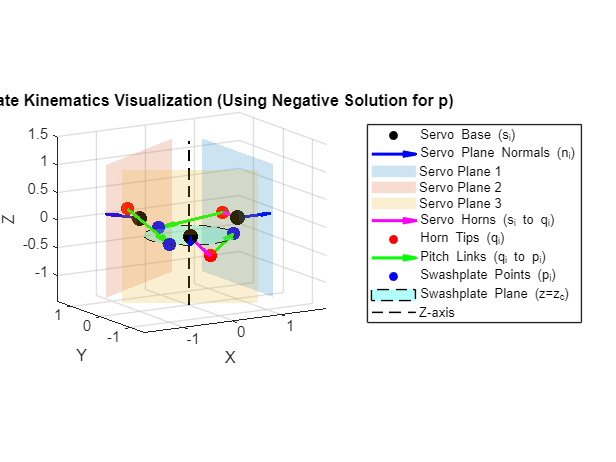


% --- Substitute symbolic variables with numerical values ---

% Substitute for s and n (servo base and normals)
local_s = double(subs(s, r, r_value));
local_n = double(subs(n, r, r_value)); % n depends only on r (and servo angles, which are fixed in s)

% Substitute for q (servo horn tips)
% q_calculated is from the main script: q_calculated = s_symbolic + delta_symbolic
% It depends on r, r_s, and theta_vec (theta_1, theta_2, theta_3)
local_q = double(subs(q_calculated, ...
                     [r, r_s, theta_1, theta_2, theta_3], ...
                     [r_value, rs_value, theta_value(1), theta_value(2), theta_value(3)]));

% Substitute for p (swashplate connection points)
% Using p_solutions_set2 for the "negative" solution set as requested.
% It depends on r, r_s, theta_vec, r_p, r_w, z_c.
local_p = double(subs(p_solutions_set2, ... % Changed from p_solutions_set1
                     [r, r_s, theta_1, theta_2, theta_3, r_p, r_w, z_c], ...
                     [r_value, rs_value, theta_value(1), theta_value(2), theta_value(3), rp_value, rw_value, zc_value]));

% --- Plotting Setup ---
figure;
hold on;
axis equal;
view(3); % Default 3D view
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Swashplate Kinematics Visualization (Using Negative Solution for p)');

% --- Plot Servo Base (s) and Normals (n) ---
scatter3(local_s(1,:), local_s(2,:), local_s(3,:), 100, 'k', 'filled', 'DisplayName', 'Servo Base (s_i)');
quiver3(local_s(1,:), local_s(2,:), local_s(3,:), ...
        local_n(1,:), local_n(2,:), local_n(3,:), ...
        0.5, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'DisplayName', 'Servo Plane Normals (n_i)');

% --- Plot Servo Planes ---
colors = lines(3); % Get 3 distinct colors
L_plane = 1.2 * r_value; % Size of the plane visualization
plane_handles = gobjects(3,1);
for i = 1:3
    ni_vec = local_n(:,i);    % Normal vector for plane i
    si_vec = local_s(:,i);    % A point on plane i (servo base)

    % Create basis vectors for the plane
    % If normal is [0;0;1] or [0;0;-1], null space needs careful handling or direct basis
    if abs(ni_vec(1)) < 1e-6 && abs(ni_vec(2)) < 1e-6 % Normal is along z-axis
        Bi_plane = [1 0; 0 1; 0 0]; % Basis for XY plane
         if ni_vec(3) < 0; Bi_plane(:,2) = -Bi_plane(:,2); end % Ensure correct orientation if normal is -z
    else
        Bi_plane = null(ni_vec'); % 3x2 basis for the plane
    end
    
    % Four corners of a square of side 2*L_plane in that plane, centered at si_vec
    corners = [ ...
        si_vec + L_plane*Bi_plane(:,1) + L_plane*Bi_plane(:,2), ...
        si_vec + L_plane*Bi_plane(:,1) - L_plane*Bi_plane(:,2), ...
        si_vec - L_plane*Bi_plane(:,1) - L_plane*Bi_plane(:,2), ...
        si_vec - L_plane*Bi_plane(:,1) + L_plane*Bi_plane(:,2)  ...
    ]';  % 4x3: each row is one vertex

    plane_handles(i) = patch('Vertices', corners, 'Faces', [1 2 3 4], ...
          'FaceColor', colors(i,:), ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'none', ...
          'DisplayName', sprintf('Servo Plane %d', i));
end

% --- Plot Servo Horns (s_i to q_i) and Horn Tips (q_i) ---
% Calculate delta vectors (q_i - s_i) numerically for plotting
delta_q_s = local_q - local_s;
quiver3(local_s(1,:), local_s(2,:), local_s(3,:), ...
        delta_q_s(1,:), delta_q_s(2,:), delta_q_s(3,:), ...
        0, 'm', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'DisplayName', 'Servo Horns (s_i to q_i)'); % 0 for no auto-scaling
scatter3(local_q(1,:), local_q(2,:), local_q(3,:), 80, 'r', 'filled', 'DisplayName', 'Horn Tips (q_i)');


% --- Plot Pitch Links (q_i to p_i) and Swashplate Points (p_i) ---
delta_p_q = local_p - local_q; % Vectors from q_i to p_i
quiver3(local_q(1,:), local_q(2,:), local_q(3,:), ...
        delta_p_q(1,:), delta_p_q(2,:), delta_p_q(3,:), ...
        0, 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'DisplayName', 'Pitch Links (q_i to p_i)'); % 0 for no auto-scaling
scatter3(local_p(1,:), local_p(2,:), local_p(3,:), 80, 'b', 'filled', 'DisplayName', 'Swashplate Points (p_i)');

% --- Plot the Plane of p_i (Swashplate Plane) ---
% This is a circle of radius rw_value at z = zc_value
phi_swash_plane = linspace(0, 2*pi, 100);
x_swash_plane = rw_value * cos(phi_swash_plane);
y_swash_plane = rw_value * sin(phi_swash_plane);
z_swash_plane = zc_value * ones(size(phi_swash_plane));
patch(x_swash_plane, y_swash_plane, z_swash_plane, 'c', ...
      'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineStyle', '--', ...
      'DisplayName', 'Swashplate Plane (z=z_c)');

% --- Plot the Z-axis ---
% Determine plot limits or set reasonable ones
current_zlim = zlim;
z_axis_min = min([-0.5, local_s(3,:), local_q(3,:), local_p(3,:), current_zlim(1), zc_value - rw_value]); % Adjusted for swashplate
z_axis_max = max([1.5, local_s(3,:), local_q(3,:), local_p(3,:), current_zlim(2), zc_value + rw_value]); % Adjusted for swashplate
plot3([0 0], [0 0], [z_axis_min z_axis_max], 'k--', 'LineWidth', 1, 'DisplayName', 'Z-axis');


% --- Labels & Legend ---
legend('Location','eastoutside');
hold off;
rotate3d on; % Allow interactive rotation


fprintf('\nPlotting complete. Check the figure window.\n');


Plotting complete. Check the figure window.


fprintf('If D_sq_i was negative for any point with the chosen parameters, local_p might contain NaNs or complex numbers.\n');

If D_sq_i was negative for any point with the chosen parameters, local_p might contain NaNs or complex numbers.


if any(isnan(local_p(:))) || any(~isreal(local_p(:)))
    fprintf('WARNING: Some p_i coordinates are NaN or complex. This means for the given parameters,\n');
    fprintf('         one or more D_sq_i (discriminant) values were negative, so no real solution exists for those p_i.\n');
    fprintf('         Try adjusting r_p, r_w, or z_c values, or check servo angles.\n');
end
